clear
clc

% Annotation text.
annot_txt = ["$ \alpha = 2^{\circ} $", "$ \alpha = 4^{\circ} $", "$ \alpha = 6^{\circ} $"];
% Legend line names.
lables = ["$ M = 0.8 $", "$ M = 0.9 $", "$ M = 1.0 $", "$ M = 1.2 $", "$ M = 1.4 $"];
% Colors.
% deep blue: #406aa4, sky blue: #50a7d3, green: #80c34a, gold: #f3af16, red: #ec2f28, magenta: #e62e90
colors = ["#406aa4", "#80c34a", "#f3af16", "#ec2f28", "#e62e90"];
% Markers.
mks = {'o', '^', 'd'};

% Wing dimensions.
span = 2.226;
root_chord = 1.000;
le_angle = 30*pi/180;
te_angle = 15.7581*pi/180;

% Calculate coordinate locations.
eta = (0.00:0.10:1.00)';
x1 = eta*span*tan(le_angle);
x2 = (eta*span*tan(te_angle) + root_chord);

% Angles of attack.
alpha_list = [2 4 6];

% Mach numbers.
mach_list = [0.80 0.90 1.00 1.20 1.40];

% Pre-allocate 3D matrices. Index by: [alpha, M, eta].
y1 = zeros([size(alpha_list'*mach_list),length(eta)]);
y2 = zeros([size(alpha_list'*mach_list),length(eta)]);
twist = zeros([size(alpha_list'*mach_list),length(eta)]);

% Loop over angles of attack and Mach numbers to get data.
num_alpha = length(alpha_list);
num_mach = length(mach_list);
num_eta = length(eta);

parfor ia = 1:num_alpha
    for im = 1:num_mach
        for ie = 1:num_eta
            [~,~,n1] = import_disp(alpha_list(ia),mach_list(im),'zDisp','le',eta(ie)); %#ok<*PFBNS> 
            y1(ia,im,ie) = max(n1);
            [~,~,n2] = import_disp(alpha_list(ia),mach_list(im),'zDisp','te',eta(ie));
            y2(ia,im,ie) = max(n2);
        end
    end
end

for ia = 1:length(alpha_list)
    for im = 1:length(mach_list)
        % Calculate distance between two points.
        d = sqrt(permute((y1(ia,im,:) - y2(ia,im,:)),[3,1,2]).^2+(x1-x2).^2);
        % Calculate the local chord length.
        dx = x2 - x1;
        % For the winglet modification, overwrite with the actual chord
        % lengths near the wingtip.
        dx(end-1:end) = [(1.565-1.162);(1.707-1.501)];
        dy = permute((y2(ia,im,:) - y1(ia,im,:)),[3,1,2]);
        % Calculate twist.
        twist(ia,im,:) = atand(dy./dx);
    end
end

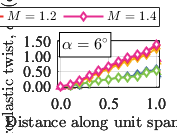

% Plot twist along span.

for ia = 1:num_alpha
    ax = axes;
    plt = gobjects(size(mach_list));

    hold on
    for im = 1:num_mach
        plt(im) = plot(eta,permute(twist(ia,im,:),[3,1,2]),Color=colors{im},LineWidth=1.5, ...
            marker=mks{ia},MarkerFaceColor='w',MarkerEdgeColor=colors{im},MarkerSize=5);
    end
    
    xlim([-0.04,1.04]);
    ylim([-0.05,1.55]);

    xtickformat('%.1f');
    ytickformat('%.2f');

    box on
    grid on

    % Text annotation.
    txt_text = text(0.05,0.9,annot_txt(ia),Units="normalized",BackgroundColor='white',Interpreter='latex',FontSmoothing='on',EdgeColor='k',Margin=2);

    xlabel('Distance along unit span, $ y/b $', Interpreter='latex',FontSize=12);
    ylabel('Aeroelastic twist, $ \alpha_{e} $ (deg)', Interpreter='latex',FontSize=12);
    
    fontname(ax,'Times New Roman');
    fontsize(ax,12,'points');
    
    lgd = legend(lables,Location='northoutside',Interpreter='latex',NumColumns=num_mach,FontSize=10);

    hold off

    % Save picture.
    exportgraphics(ax,"C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6-modified\graphs\Mod. Winglet, Aeroelastic Twist, "+num2str(alpha_list(ia))+" deg.png",'Resolution',600)

end